# ICE5: Quadratic TF Responses with Common Features

#### Step Response for Constant Settling Time

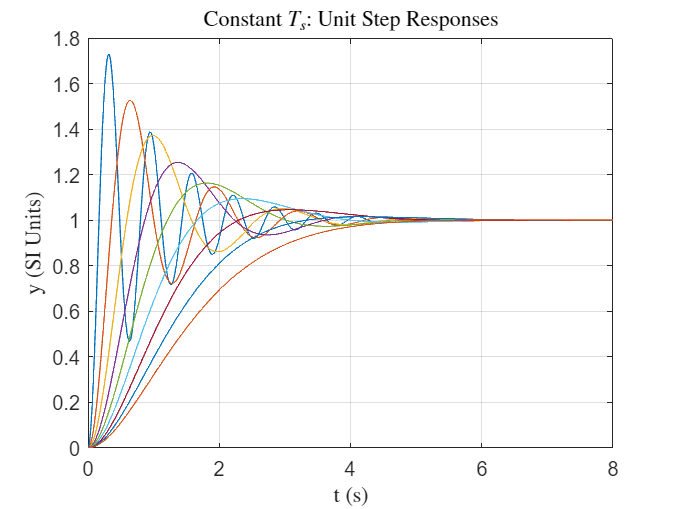

Tfinal = 8; % final time
t = (0:0.001:1) * Tfinal; % simulation time

Ts = 4; % fixed settling time
zeta = 0.1:0.1:0.9; % range of damping ratio values
itot = length(zeta);

for i = 1:itot % compute poles at each damping ratio value
    omega_n = 4/(Ts*zeta(i)); % compute natural frequency
    num = omega_n*omega_n; % numerator quadratic transfer function
    den = [1 2*zeta(i)*omega_n omega_n*omega_n]; % denominator
    DYN = tf(num, den); % transfer function object
    y = step(DYN, t); % compute step response
    yplot(i, :) = y; % store output in array
end

% plot
plot(t,yplot)
grid
xlabel('t (s)','Interpreter','latex');
ylabel('y (SI Units)','Interpreter','latex')
title('Constant $T_s$: Unit Step Responses','Interpreter','latex')

#### Step Response for Constant Peak Time

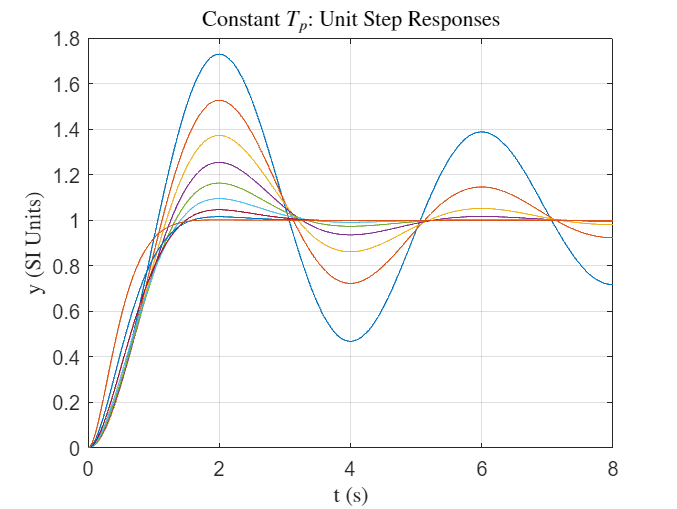

Tfinal = 8; % final time
t = (0:0.001:1) * Tfinal; % simulation time

Tp = 2; % fixed peak time
zeta = 0.1:0.1:0.9; % range of damping ratio values
itot = length(zeta);

for i = 1:itot % compute poles at each damping ratio value
    omega_n = pi / (Tp * sqrt(1-zeta(i)^2)); % compute natural frequency
    num = omega_n*omega_n; % numerator quadratic transfer function
    den = [1 2*zeta(i)*omega_n omega_n*omega_n]; % denominator
    DYN = tf(num, den); % transfer function object
    y = step(DYN, t); % compute step response
    yplot(i, :) = y; % store output in array
end

% plot
plot(t,yplot)
grid
xlabel('t (s)','Interpreter','latex');
ylabel('y (SI Units)','Interpreter','latex')
title('Constant $T_p$: Unit Step Responses','Interpreter','latex')

#### Step Response for Constant Percent Overshoot

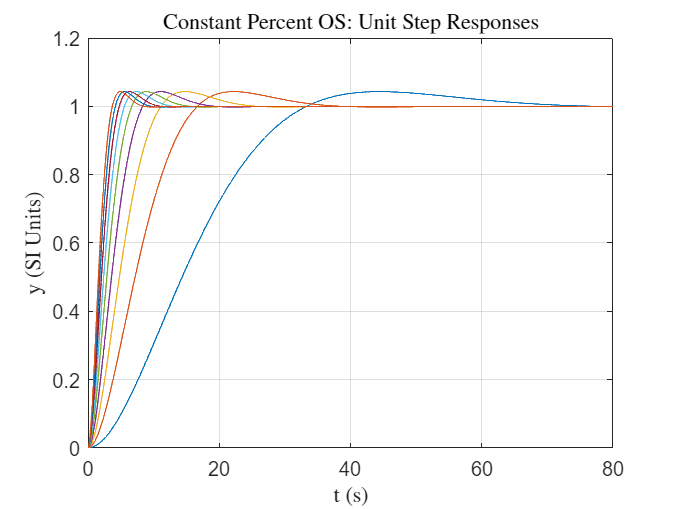

Tfinal = 80; % final time
t = (0:0.001:1) * Tfinal; % simulation time

zeta = 0.707143; % fixed damping ratio
omega_n = 0.1:0.1:0.9; % range natural frequency values
itot = length(omega_n);

for i = 1:itot % compute poles at each damping ratio value
    num = omega_n(i)*omega_n(i); % numerator quadratic transfer function
    den = [1 2*zeta*omega_n(i) omega_n(i)*omega_n(i)]; % denominator
    DYN = tf(num, den); % transfer function object
    y = step(DYN, t); % compute step response
    yplot(i, :) = y; % store output in array
end

% plot
plot(t,yplot)
grid
xlabel('t (s)','Interpreter','latex');
ylabel('y (SI Units)','Interpreter','latex')
title('Constant Percent OS: Unit Step Responses','Interpreter','latex')

#### Step Response for Constant Natural Frequency

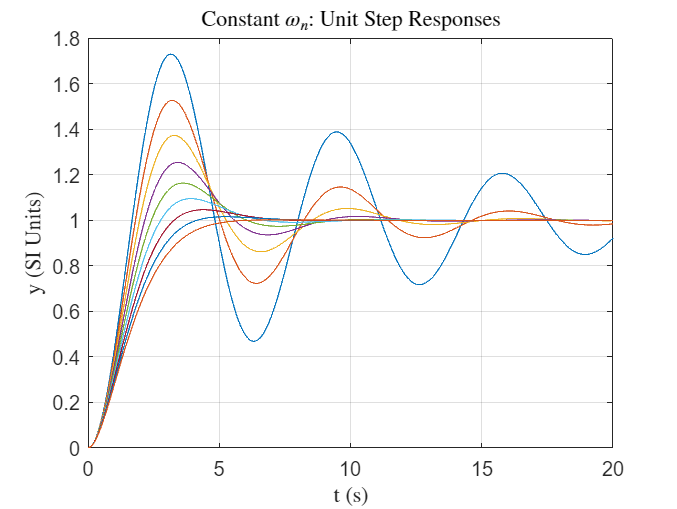

Tfinal = 20; % final time
t = (0:0.001:1) * Tfinal; % simulation time

omega_n = 1;
zeta = 0.1:0.1:0.9; % range of damping ratio values
itot = length(zeta);

for i = 1:itot % compute poles at each damping ratio value
    num = omega_n*omega_n; % numerator quadratic transfer function
    den = [1 2*zeta(i)*omega_n omega_n*omega_n]; % denominator
    DYN = tf(num, den); % transfer function object
    y = step(DYN, t); % compute step response
    yplot(i, :) = y; % store output in array
end

% plot
plot(t,yplot)
grid
xlabel('t (s)','Interpreter','latex');
ylabel('y (SI Units)','Interpreter','latex')
title('Constant $\omega_n$: Unit Step Responses','Interpreter','latex')